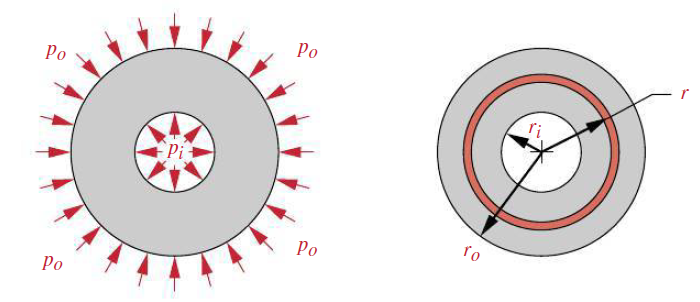

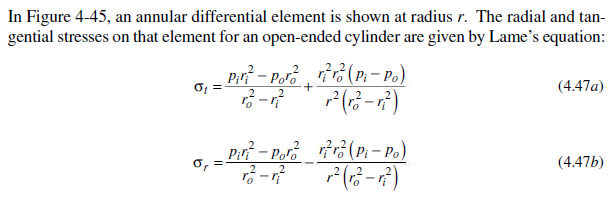

 **thick walled (i.e. t > r/10 ):**

Thickest radius = 60.56 mm

Radius to flatspot = 57.93 mm

Inner radius = 31.5 mm

t_1: Thickest thickness = 29.06 mm

t_2: Thickness from sensor trench to outer diameter = 14.23 mm

t_3: Thickness from sensor trench to flatspot = 11.6 mm

How small must outer radius be in order to considered thin-walled?

syms r
r_o_thin_threshold = solve(r-31.5==r/10,r)

$$r\_o\_thin\_threshold = 35$$

thickness_of_thickest_thin_wall = round(r_o-31.5,3)

thickness_of_thickest_thin_wall = -31.4390

Close-ended equation:

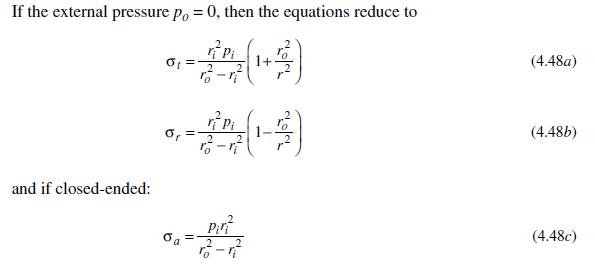

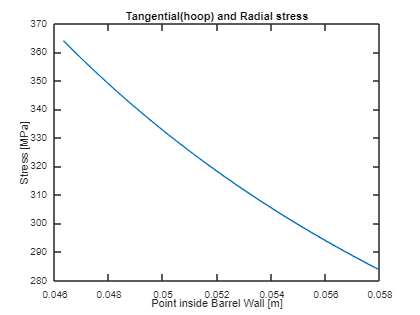

r_i = 46.33 * 10^(-3); %31.5 * 10^(-3); % m
r_o = r_i + 11.6 * 10^(-3); %57.93 * 10^(-3);% m
p_i = 400*10^5 * 2; % Pa + SF
syms r 
n = 100;

r = linspace(r_i,r_o, n);
sigma_t = ((r_i^2*p_i)/(r_o^2-r_i^2) * (1 + r_o^2./r.^2))*10^-6;
sigma_r = ((r_i^2*p_i)/(r_o^2-r_i^2) * (1 - r_o^2./r.^2))*10^-6;
sigma_a = linspace(0,0,n);
sigma_a(:) = ((r_i^2*p_i)/(r_o^2-r_i^2)) * 10^-6 ;


plot(r,sigma_t)
title("Tangential(hoop) and Radial stress")
xlabel("Point inside Barrel Wall [m]")
ylabel("Stress [MPa]")
hold off;

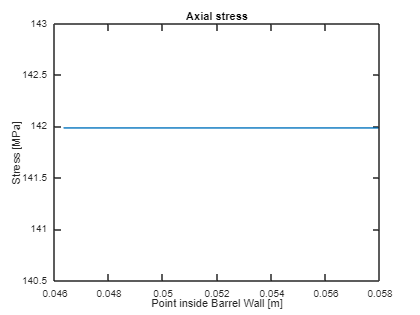


plot(r,sigma_a)
title("Axial stress")
xlabel("Point inside Barrel Wall [m]")
ylabel("Stress [MPa]")

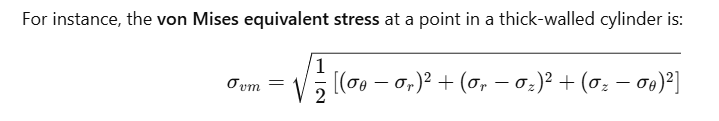

Source: [https://www.ijraset.com/fileserve.php?FID=24534#:~:text=The%20above%20three%20stress%20represent%20the%20principle,location%20were%20done%20by%20the%20equation%208.](https://www.ijraset.com/fileserve.php?FID=24534#:~:text=The%20above%20three%20stress%20represent%20the%20principle,location%20were%20done%20by%20the%20equation%208.) 

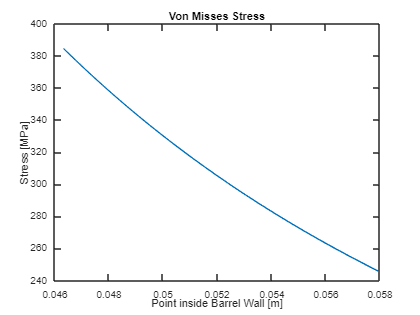

sigma_VM = sqrt( 0.5 * ( (sigma_t-sigma_r).^2 + (sigma_r - sigma_a).^2 + (sigma_a - sigma_t).^2));
plot(r,sigma_VM)
title("Von Misses Stress")
xlabel("Point inside Barrel Wall [m]")
ylabel("Stress [MPa]")

## How thin can the barrel be, if intermediate section is used:

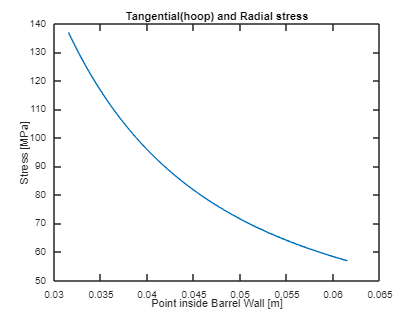

r_i = (63/2) * 10^(-3); %Bore radius  [m]
Wall_thickness = 30 * 10^(-3); % [m]
r_o = r_i + Wall_thickness; %;% m
p_i = 400*10^5 * 2; % Pa + SF
syms r 
n = 100;

r = linspace(r_i,r_o, n);
sigma_t = ((r_i^2*p_i)/(r_o^2-r_i^2) * (1 + r_o^2./r.^2))*10^-6;
sigma_r = ((r_i^2*p_i)/(r_o^2-r_i^2) * (1 - r_o^2./r.^2))*10^-6;
sigma_a = linspace(0,0,n);
sigma_a(:) = ((r_i^2*p_i)/(r_o^2-r_i^2)) * 10^-6 ;


plot(r,sigma_t)
title("Tangential (hoop) stress")
xlabel("Point inside Barrel Wall [m]")
ylabel("Stress [MPa]")
hold off;

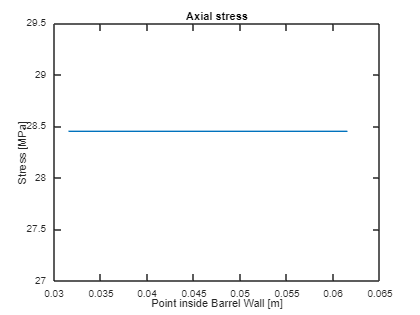


 
plot(r,sigma_r)
title("Radial stress")
xlabel("Point inside Barrel Wall [m]")
ylabel("Stress [MPa]")
hold off;


plot(r,sigma_a)
title("Axial stress")
xlabel("Point inside Barrel Wall [m]")
ylabel("Stress [MPa]")

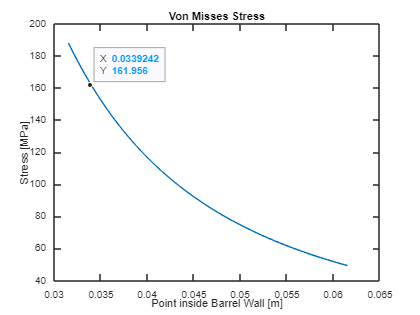


sigma_VM = sqrt( 0.5 * ( (sigma_t-sigma_r).^2 + (sigma_r - sigma_a).^2 + (sigma_a - sigma_t).^2));
plot(r,sigma_VM)
title("Von Misses Stress")
xlabel("Point inside Barrel Wall [m]")
ylabel("Stress [MPa]")

## Different thicknesses, if intermediate section is required:

How small must outer radius be in order to considered thin-walled?

syms r
r_o_thin_threshold = solve(r-31.5==r/10,r)

$$r\_o\_thin\_threshold = 35$$


r_i = (63/2) * 10^(-3); %Bore radius  [m]

%Plotting the stresses in the walls:

w_t1 = 30 * 10^(-3); % [m] Wall_thickness
r_o_1 = r_i + w_t1; %;% m Outer wall

p_i = 400*10^5 * 2; % Pa + SF
syms r 
n = 100;

r = linspace(r_i,r_o_1, n);
sigma_t = ((r_i^2*p_i)/(r_o_1^2-r_i^2) * (1 + r_o_1^2./r.^2))*10^-6;
sigma_r = ((r_i^2*p_i)/(r_o_1^2-r_i^2) * (1 - r_o_1^2./r.^2))*10^-6;
sigma_a = linspace(0,0,n);
sigma_a(:) = ((r_i^2*p_i)/(r_o_1^2-r_i^2)) * 10^-6 ;
sigma_VM = sqrt( 0.5 * ( (sigma_t-sigma_r).^2 + (sigma_r - sigma_a).^2 + (sigma_a - sigma_t).^2));

w_t2 = 25 * 10^(-3); % [m] Wall_thickness
r_o_2 = r_i + w_t2; %;% m Outer wall

r = linspace(r_i,r_o_2, n);
sigma_t2 = ((r_i^2*p_i)/(r_o_2^2-r_i^2) * (1 + r_o_2^2./r.^2))*10^-6;
sigma_r2 = ((r_i^2*p_i)/(r_o_2^2-r_i^2) * (1 - r_o_2^2./r.^2))*10^-6;
sigma_a2 = linspace(0,0,n);
sigma_a2(:) = ((r_i^2*p_i)/(r_o_2^2-r_i^2)) * 10^-6 ;
sigma_VM2 = sqrt( 0.5 * ( (sigma_t2-sigma_r2).^2 + (sigma_r2 - sigma_a2).^2 + (sigma_a2 - sigma_t2).^2));
r_2 = linspace(r_i,r_o_2, n);

w_t3 = 20 * 10^(-3); % [m] Wall_thickness
r_o_3 = r_i + w_t3; %;% m Outer wall

r = linspace(r_i,r_o_3, n);
sigma_t3 = ((r_i^2*p_i)/(r_o_3^2-r_i^2) * (1 + r_o_3^2./r.^2))*10^-6;
sigma_r3 = ((r_i^2*p_i)/(r_o_3^2-r_i^2) * (1 - r_o_3^2./r.^2))*10^-6;
sigma_a3 = linspace(0,0,n);
sigma_a3(:) = ((r_i^2*p_i)/(r_o_3^2-r_i^2)) * 10^-6 ;
sigma_VM3 = sqrt( 0.5 * ( (sigma_t3-sigma_r3).^2 + (sigma_r3 - sigma_a3).^2 + (sigma_a3 - sigma_t3).^2));
r_3 = linspace(r_i,r_o_3, n);

w_t4 = 15 * 10^(-3); % [m] Wall_thickness
r_o_4 = r_i + w_t4; %;% m Outer wall

r = linspace(r_i,r_o_4, n);
sigma_t4 = ((r_i^2*p_i)/(r_o_4^2-r_i^2) * (1 + r_o_4^2./r.^2))*10^-6;
sigma_r4 = ((r_i^2*p_i)/(r_o_4^2-r_i^2) * (1 - r_o_4^2./r.^2))*10^-6;
sigma_a4 = linspace(0,0,n);
sigma_a4(:) = ((r_i^2*p_i)/(r_o_4^2-r_i^2)) * 10^-6 ;
sigma_VM4 = sqrt( 0.5 * ( (sigma_t4-sigma_r4).^2 + (sigma_r4 - sigma_a4).^2 + (sigma_a4 - sigma_t4).^2));
r_4 = linspace(r_i,r_o_4, n);

w_t5 = 10 * 10^(-3); % [m] Wall_thickness
r_o_5 = r_i + w_t5; %;% m Outer wall

r = linspace(r_i,r_o_5, n);
sigma_t5 = ((r_i^2*p_i)/(r_o_5^2-r_i^2) * (1 + r_o_5^2./r.^2))*10^-6;
sigma_r5 = ((r_i^2*p_i)/(r_o_5^2-r_i^2) * (1 - r_o_5^2./r.^2))*10^-6;
sigma_a5 = linspace(0,0,n);
sigma_a5(:) = ((r_i^2*p_i)/(r_o_5^2-r_i^2)) * 10^-6 ;
sigma_VM5 = sqrt( 0.5 * ( (sigma_t5-sigma_r5).^2 + (sigma_r5 - sigma_a5).^2 + (sigma_a5 - sigma_t5).^2));
r_5 = linspace(r_i,r_o_5, n);

w_t6 = 5 * 10^(-3); % [m] Wall_thickness
r_o_6 = r_i + w_t6; %;% m Outer wall

r = linspace(r_i,r_o_6, n);
sigma_t6 = ((r_i^2*p_i)/(r_o_6^2-r_i^2) * (1 + r_o_6^2./r.^2))*10^-6;
sigma_r6 = ((r_i^2*p_i)/(r_o_6^2-r_i^2) * (1 - r_o_6^2./r.^2))*10^-6;
sigma_a6 = linspace(0,0,n);
sigma_a6(:) = ((r_i^2*p_i)/(r_o_6^2-r_i^2)) * 10^-6 ;
sigma_VM6 = sqrt( 0.5 * ( (sigma_t6-sigma_r6).^2 + (sigma_r6 - sigma_a6).^2 + (sigma_a6 - sigma_t6).^2));
r_6 = linspace(r_i,r_o_6, n);

r = linspace(r_i,r_o_1, n);

plot(r,sigma_t)
hold on 
plot(r_2,sigma_t2)
hold on 
plot(r_3,sigma_t3)
hold on 
plot(r_4,sigma_t4)
hold on 
plot(r_5,sigma_t5)
hold on 
plot(r_6,sigma_t6)
title("Tangential (hoop) stress")
xlabel("Point inside Barrel Wall [m]")
ylabel("Stress [MPa]")
ylim([0 560])
l = legend("30","25","20","15","10","5", "Position", [0.6086 0.5983 0.2446, 0.2583]);
[hleg,att] = legend('show');

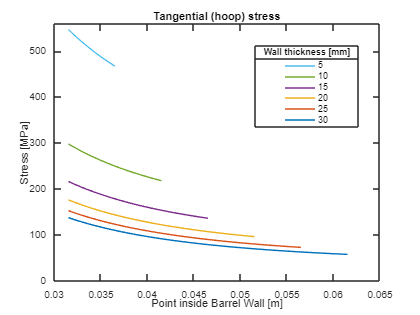

title(hleg,'Wall thickness [mm]');
hleg.Title.NodeChildren.Position;
l.Direction = 'reverse';

hold off;


plot(r,sigma_r)
hold on 
plot(r_2,sigma_r2)
hold on 
plot(r_3,sigma_r3)
hold on 
plot(r_4,sigma_r4)
hold on 
plot(r_5,sigma_r5)
hold on 
plot(r_6,sigma_r6)
title("Radial stress")
xlabel("Point inside Barrel Wall [m]")
ylabel("Stress [MPa]")
l = legend("30","25","20","15","10","5", "Position", [0.6086 0.5983 0.2446, 0.2583]);
[hleg,att] = legend('show');

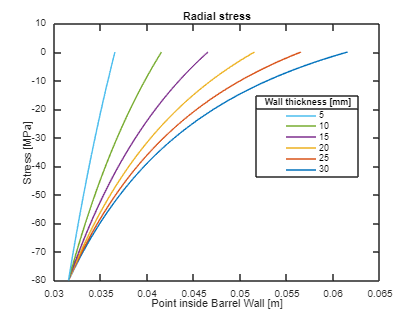

title(hleg,'Wall thickness [mm]');
hleg.Title.NodeChildren.Position;
l.Direction = 'reverse';
hold off;

legend(["30", "25", "20", "15", "10", "5"], "Direction", "reverse", "Position", [0.6102 0.4408 0.2446, 0.2583])


plot(r,sigma_a)
hold on
plot(r_2,sigma_a2)
hold on 
plot(r_3,sigma_a3)
hold on 
plot(r_4,sigma_a4)
hold on 
plot(r_5,sigma_a5)
hold on 
plot(r_6,sigma_a6)

title("Axial stress")
xlabel("Point inside Barrel Wall [m]")
ylabel("Stress [MPa]")
l = legend("30","25","20","15","10","5");
[hleg,att] = legend('show');

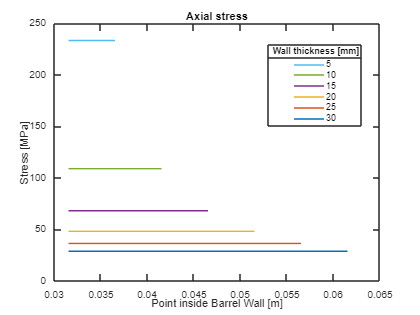

title(hleg,'Wall thickness [mm]');
hleg.Title.NodeChildren.Position;
l.Direction = 'reverse';
hold off

legend(["30", "25", "20", "15", "10", "5"], "Direction", "reverse", "Position", [0.6400 0.6028 0.2214, 0.2583])


sigma_VM = sqrt( 0.5 * ( (sigma_t-sigma_r).^2 + (sigma_r - sigma_a).^2 + (sigma_a - sigma_t).^2));
plot(r,sigma_VM)
hold on
plot(r_2,sigma_VM2)
hold on 
plot(r_3,sigma_VM3)
hold on 
plot(r_4,sigma_VM4)
hold on 
plot(r_5,sigma_VM5)
hold on 
plot(r_6,sigma_VM6)
title("Von Misses Stress")
xlabel("Point inside Barrel Wall [m]")
ylabel("Stress [MPa]")
l = legend("30","25","20","15","10","5");
[hleg,att] = legend('show');

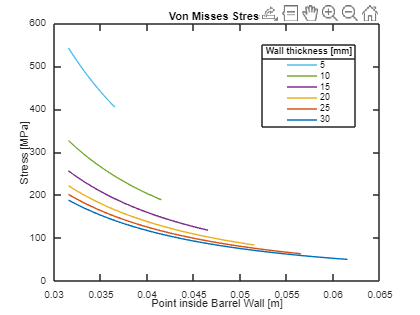

title(hleg,'Wall thickness [mm]');
hleg.Title.NodeChildren.Position;
l.Direction = 'reverse';
hold off

legend(["30", "25", "20", "15", "10", "5"], "Direction", "reverse", "Position", [0.6255 0.6007 0.2214, 0.2583])